# EQUACIONS DIFERENCIALS (II)

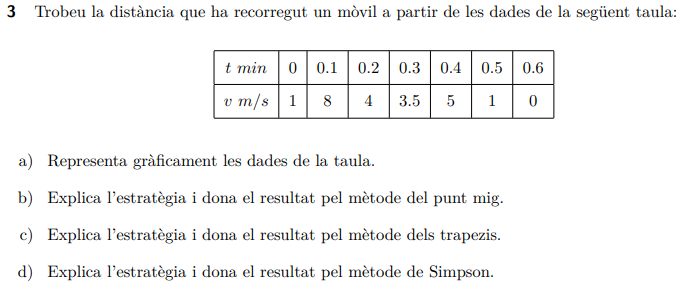

format shortG
time = linspace(0,0.6,7);
vel = [1 8 4 3.5 5 1 0];
t = time*60;

- a)

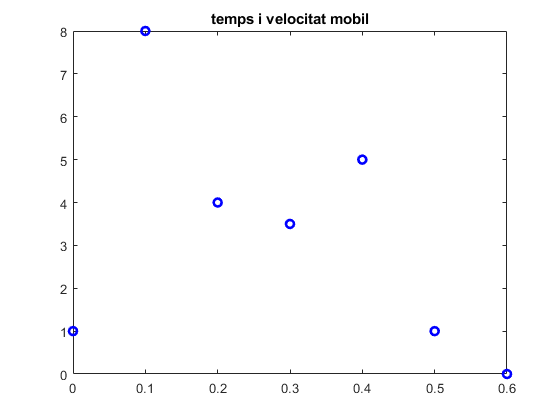

plot(time,vel,'bo', 'LineWidth',2), title('temps i velocitat mobil')

- b)

h = (time(3)-time(1))*60;
w = [0 1 0 1 0 1 0];    % només compten els punts mitjos
I_m = h*sum(w.*vel)

I_m =           150


- c)

I_t = trapz(t,vel)

I_t =           132


- d)

w = [1 4 2 4 2 4 1];    % pesos (podia fer un bucle)
h = 0.1*60;
I_s = h/3*sum(w.*vel)

I_s =    138


    k    f(_)      f         error       xifres
    _    ____    ______    __________    ______

    5    0.1     1.7683    2.3327e-08      7   



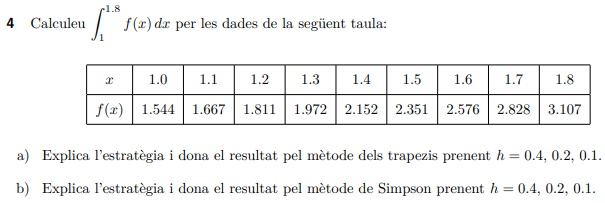

x = 1.0:0.1:1.8;
fx = [1.544 1.667 1.811 1.972 2.152 2.351 2.576 2.828 3.107];

- Representa gràficament les dades de la taula

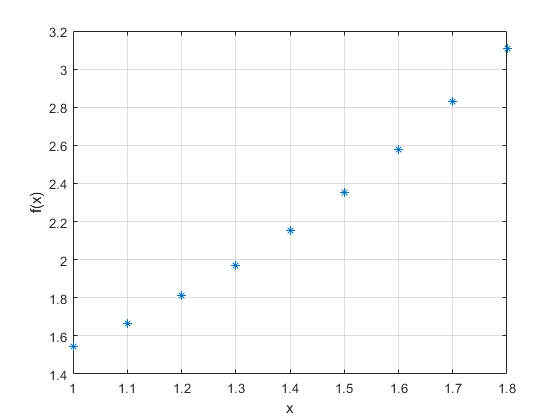

plot(x,fx,'*')
grid on
ylabel('f(x)')
xlabel('x')

- Explica l'estratègia i dona el resultat pel mètode dels trapezis prenent h=0.4,0.2 i 0.1

f = @(t) fx(int8(mod(t,1)+1)); 
n = 6; a = 1; b = 1.8;
ve = integral(f,a,b);
h = [0.4, 0.2, 0.1]; TT = [];
for i = 1:length(h)
    x = a:h(i):b; y = f(x);
    w = [1 2*ones(1,length(y)-2) 1];
    valor = sum(y.*w*(h(i)/2));
    TT = [TT; h(i), valor, abs(valor-ve), fix(-log10(2*abs(valor-ve)))];
end
taula = array2table(TT,'VariableNames',{'h','f(_)','error','xifres'}); disp(taula)

     h      f(_)       error      xifres
    ___    ______    _________    ______
    0.4    1.2598       0.0123      1   
    0.2    1.2721    2.088e-07      6   
    0.1    1.2783    0.0061498      1   


- Explica l'estratègia i dona el resultat pel mètode de Simpson prenent h=0.4,0.2 i 0.1

h = [0.4, 0.2, 0.1]; TS = [];
for i = 1:length(h)
    x = a:h(i):b; y = f(x);
    w = 4*ones(1,length(y)-2);
    w(2:2:end) = 2;
    w = [1 w 1];
    valor = sum(y.*w*(h(i)/3));
     TS = [TS; h(i), valor, abs(valor-ve), fix(-log10(2*abs(valor-ve)))];
end
taula = array2table(TS,'VariableNames',{'h','f(_)','error','xifres'}); disp(taula)

     h      f(_)       error      xifres
    ___    ______    _________    ______
    0.4    1.2516       0.0205      1   
    0.2    1.2762    0.0040998      2   
    0.1    1.2803    0.0081998      1   


% a
f = @(x) sqrt(x)*sin(x);
romberg(f,0,1,4)

ans =       0.42074            0            0            0
      0.37987      0.36625            0            0
      0.36844      0.36463      0.36452            0
      0.36533       0.3643      0.36428      0.36427


% b
f = @(x) 1/sqrt(1+x^4);
romberg(f,0,1,4)

ans =       0.85355            0            0            0
      0.91185      0.93128            0            0
      0.92333      0.92716      0.92688            0
      0.92612      0.92704      0.92704      0.92704


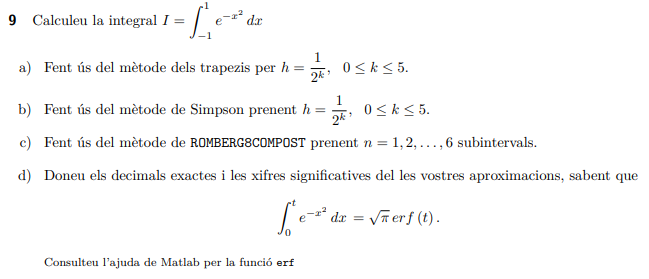

f = @(x) exp(-x.^2);
ve = integral(f,-1,1)

ve =        1.4936

% Métode de Trapezis
k = 0:5; a = -1; b = 1;
my_trap(f,a,b,k);

    k       h        f(_)       error       xifres
    _    _______    ______    __________    ______
    0          1    1.3679       0.12577      0   
    1        0.5    1.4627      0.030908      1   
    2       0.25     1.486     0.0076801      1   
    3      0.125    1.4917      0.001917      2   
    4     0.0625    1.4932    0.00047907      3   
    5    0.03125    1.4935    0.00011976      3   


% Mètode de Simpson
k = 0:5; a = -1; b = 1;
my_simp(f,a,b,k);

    k       h        f(_)       error       xifres
    _    _______    ______    __________    ______
    0          1    1.5786      0.084938      0   
    1        0.5    1.4944    0.00071259      2   
    2       0.25    1.4937    6.2494e-05      3   
    3      0.125    1.4937    3.9754e-06      5   
    4     0.0625    1.4936    2.4925e-07      6   
    5    0.03125    1.4936    1.5589e-08      7   


% Mètode de Montecarlo
format longG
a = -1; b = 1; k = 1:6;
my_montecarlo(f,a,b,k);

    k       M             f(_)                 error            xifres
    _    _______    ________________    ____________________    ______
    1         10    1.64427105501194       0.150622789387089      0   
    2        100    1.42841498029097      0.0652332853338833      0   
    3       1000    1.48528194118823     0.00836632443662833      1   
    4      10000    1.49938085659068     0.00573259096582435      1   
    5     100000     1.4931130081818    0.000535257443058379      2   
    6    1000000    1.49369923900289    5.09733780409416e-05      3   
